## IE311 - Aula Prática 1

## Simulador SAR

**Exercício 1**

Considere a geometria apresentada na figura abaixo:

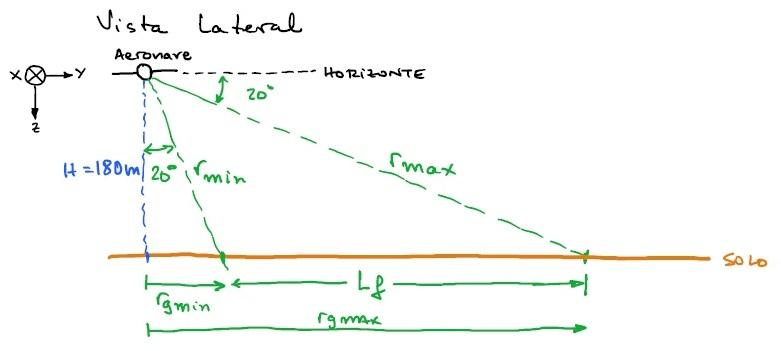

Calcule:

- Os alcances de visada direta mínimo e máximo (Rmin e Rmax);

- Os alcances no solo mínimo e máximo (Rgmin e Rgmax);

- A largura de faixa (Lf).

H=180;                  % Altura da aeronave
theta=deg2rad(20);      % Ângulo entre o feixe da antena e a vertical/horizontal

% cos(theta) = H/Rmin
Rmin = H/cos(theta)

Rmin = 191.5520

Rmax = H/sin(theta)

Rmax = 526.2848

Rgmin = H*tan(theta)

Rgmin = 65.5146

Rgmax = H/tan(theta)

Rgmax = 494.5459

Lf = Rgmax - Rgmin

Lf = 429.0313

**Exercício 2**

A aeronave voa em linha reta, a 180 m acima do solo e com velocidade constante de 100 km/h. O eixo x indica a direção de voo; o eixo y, a direção ortogonal à direção de voo, à direita; e o eixo z, a direção vertical, apontando para o centro da terra. A trajetória da aeronave se inicia em (0, 0, -180) e termina em (500, 0, -180).

Amostre a trajetória da aeronave, considerando que o radar emite pulsos a cada 1,515 ms.

Ve = 100/3.6;   % Velocidade escalar do radar [m/s]
PRT = 1.515e-3; % Tempo de repetição de pulso (pulse repetition time)

% Escreva seu código aqui
x = 0:Ve*PRT:500;
y = zeros(size(x));
z = -H*ones(size(x));

P = [x' y' z']

P =          0         0 -180.0000
    0.0421         0 -180.0000
    0.0842         0 -180.0000
    0.1263         0 -180.0000
    0.1683         0 -180.0000
    0.2104         0 -180.0000
    0.2525         0 -180.0000
    0.2946         0 -180.0000
    0.3367         0 -180.0000
    0.3788         0 -180.0000


**Exercício 3**

Há dois alvos pontuais no solo:

- R1 na posição (230, Rgmin + 2*Lf/5, 0) com taxa de reflexão igual a 50;

- R2 na posição (270, Rgmin + 3*Lf/5, 0) com taxa de reflexão igual a 100.

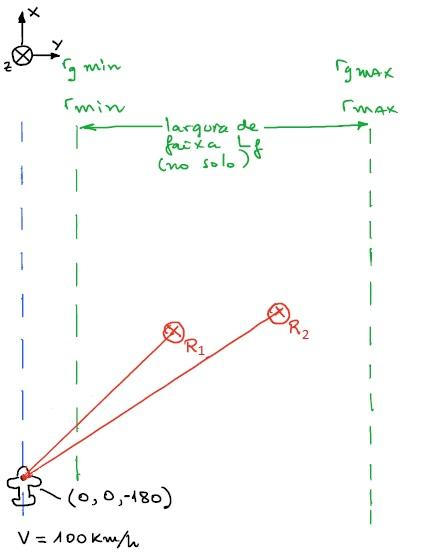

A antena do radar tem uma abertura em azimute de 20 graus e centrada na linha ortogonal à direção de voo, conforme a figura abaixo:

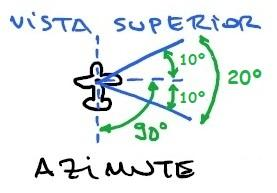

**a) **Verifique que, quando o radar está na posição (0, 0, -180), nenhum dos alvos é iluminado.

V = [Ve 0 0];               % Velocidade vetorial do radar           
R1 = [230 Rgmin+2*Lf/5 0];  % Posição do alvo 1
R2 = [270 Rgmin+3*Lf/5 0];  % Posição do alvo 2
hrwBW = 20;                 % Abertura horizontal da antena

% Vetores que apontam do radar para cada alvo
range1a = R1-P(1,:);
range2a = R2-P(1,:);



%Ângulo entre a velocidade e os vetores definidos acima
angle1a = acosd(dot(V/norm(V),range1a/norm(range1a)));
angle2a = acosd(dot(V/norm(V),range2a/norm(range2a)));
test1a = angle1a > 90 -hrwBW/2 && angle1a < 90+hrwBW/2;
test2a = angle2a > 90 -hrwBW/2 && angle2a < 90+hrwBW/2;

**b)** Verifique que, quando o radar está na posição (250, 0, -180), ambos os alvos são iluminados.

[~,n] = min(abs(250-x))

n = 5942

% Vetores que apontam do radar para cada alvo
range1b = R1-P(n,:);
range2b = R2-P(n,:);

%Ângulo entre a velocidade e os vetores definidos acima
angle1b = acosd(dot(V/norm(V),range1b/norm(range1b)));
angle2b = acosd(dot(V/norm(V),range2b/norm(range2b)));
test1b = angle1b > 90 -hrwBW/2 && angle1b < 90+hrwBW/2

test1b = logical
   1


test2b = angle2b > 90 -hrwBW/2 && angle2b < 90+hrwBW/2

test2b = logical
   1


**Exercício 4**

Para cada pulso emitido pelo radar, o sinal de retorno é amostrado a uma taxa de 120 MHz, com 512 amostras. A amostragem do radar se inicia junto com a transmissão do pulso. Mostre o sinal de retorno do radar referente a um pulso emitido no instante em que o radar se encontra na posição (250, 0, -180). Essa linha de 512 amostras é chamada de linha de alcance ou *range line*.

Considerações:

- Cada alvo pontual deve aparecer na linha de 512 pontos como uma única amostra. Caso ele fique entre duas amostras, deve-se escolher a amostra com a melhor aproximação ao alcance de visada direta do alvo;

- A amplitude do alvo amostrado é dada pela sua taxa de reflexão (ver exercício anterior).

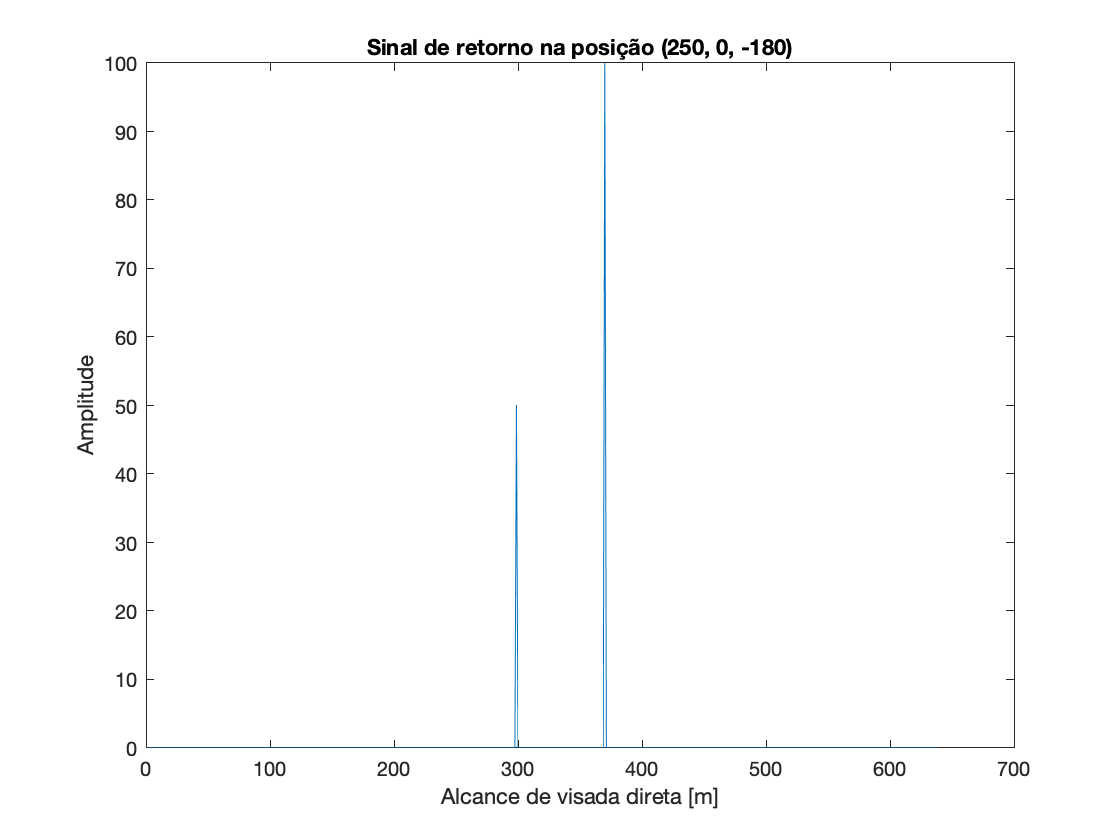

fs = 120e6;     % Taxa de amostragem
Ns = 512;       % Número de amostras
ampR1 = 50;
ampR2 = 100;

D1 = norm(range1b);
D2 = norm(range2b);

spaceTime = 150/1e-6; %Relacao espaço-tempo: 150m <--> 1 us
rngIncrement = spaceTime/fs; % Diferença de alcance (de visada direta) entre duas amostras sucessivas

signal = zeros(1,Ns);
rngBin1 = D1/rngIncrement +1;
rngBin2 = D2/rngIncrement +1;
signal(round(rngBin1)) = ampR1;
signal(round(rngBin2)) = ampR2;

rngAxis = (0:Ns-1)*rngIncrement;
plot(rngAxis,signal)
xlabel('Alcance de visada direta [m]')
ylabel('Amplitude')
title('Sinal de retorno na posição (250, 0, -180)')

# **TAREFA**

Gere os dados brutos do radar como uma variável bidimensional com os eixos azimute e alcance de visada direta, tal que:

- O eixo de azimute (ou direção de voo) corresponde à trajetória de 500 m discretizada em relação aos pulsos de transmissão;

- O eixo de alcance de visada direta se refere às 512 amostras do sinal de retorno;

- A amplitude do alvo é igual à sua taxa de reflexão (quando ele é iluminado pelo radar), ou é zero (quando não é iluminado);

- A fase do alvo ainda não é representada.

Apresente essa variável através de uma imagem com vista de cima e também em perspectiva.

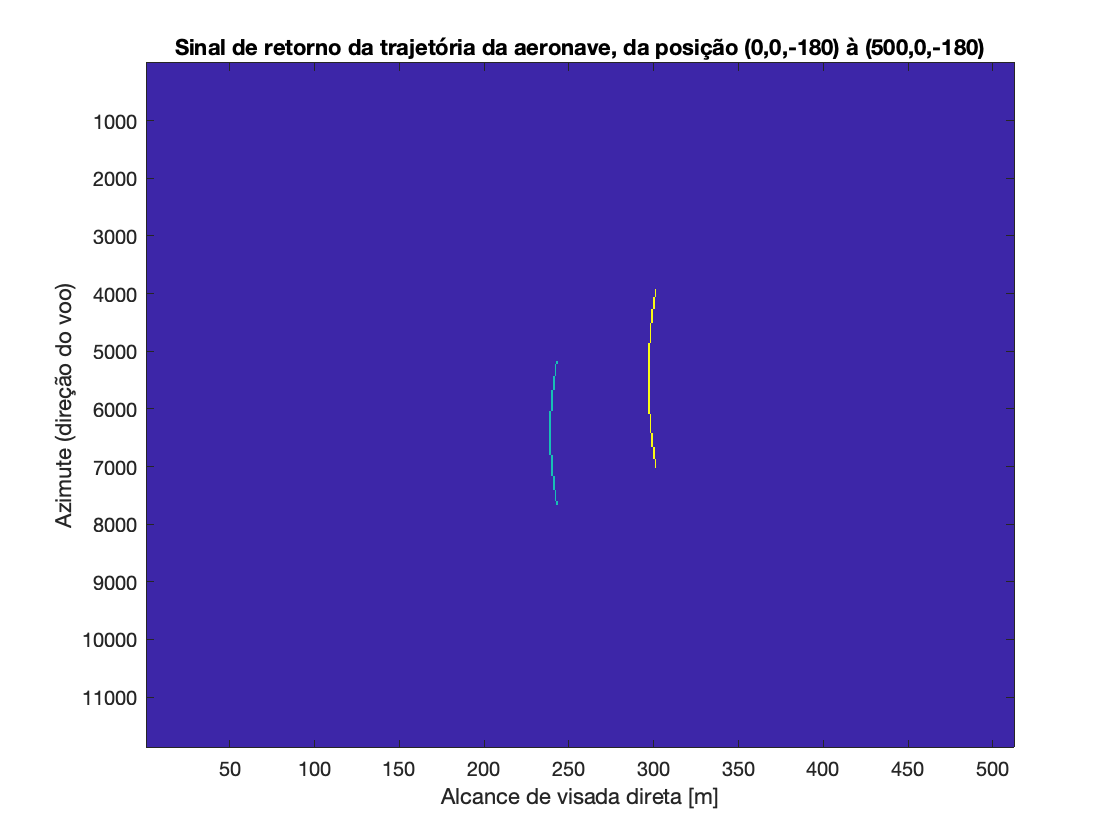

% imagesc -> vista de cima 
% mesh      -> vista perspectiva
%eixo de azimute nesse radar tá relacionado com a posicao do radar em relacao aos alvos
%d = r2 - p
% -> dai define o rangebin de cada vez que o alvo consegur ser visto pelo radar 

% Vetores que apontam de cada posicao do radar para cada alvo
rangeAlvo1 = R1-P;
rangeAlvo2 = R2-P;
%  Distancia dos alvos para cada posicao do radar
D1_pos_radar =sqrt(sum(rangeAlvo1.^2,2));
D2_pos_radar = sqrt(sum(rangeAlvo2.^2,2));

% Matriz do sinal: direcao do voo x visada direta
matriz_signal = zeros(length(x),Ns);

rngBinsAlvo1 = round(D1_pos_radar/rngIncrement) +1;
rngBinsAlvo2 = round(D2_pos_radar/rngIncrement) +1;


%para cada instante t da trajetoria da aeronave
for t = 1:size(matriz_signal,1)
    
   
    angleAlvo1_t = acosd(dot(V/norm(V),rangeAlvo1(t,:)/norm(rangeAlvo1(t,:))));
    angleAlvo2_t = acosd(dot(V/norm(V),rangeAlvo2(t,:)/norm(rangeAlvo2(t,:))));
    
     %chega se o alvo 1 está na visada do radar
    isAlvo1Visivel = angleAlvo1_t > 90 -hrwBW/2 && angleAlvo1_t < 90+hrwBW/2;
    isAlvo2Visivel = angleAlvo2_t > 90 -hrwBW/2 && angleAlvo2_t < 90+hrwBW/2;
    
    %se o alvo estiver na visada do radar, ele eh detectado pelo radar 
    if isAlvo1Visivel, matriz_signal(end+1-t, rngBinsAlvo1(t)) = ampR1; end
    if isAlvo2Visivel, matriz_signal(end+1-t, rngBinsAlvo2(t)) = ampR2; end   
    
end

% Plot "visao de cima"

imagesc(matriz_signal)
zticks(x)
xlabel('Alcance de visada direta [m]')
ylabel('Azimute (direção do voo)')
title('Sinal de retorno da trajetória da aeronave, da posição (0,0,-180) à (500,0,-180)')

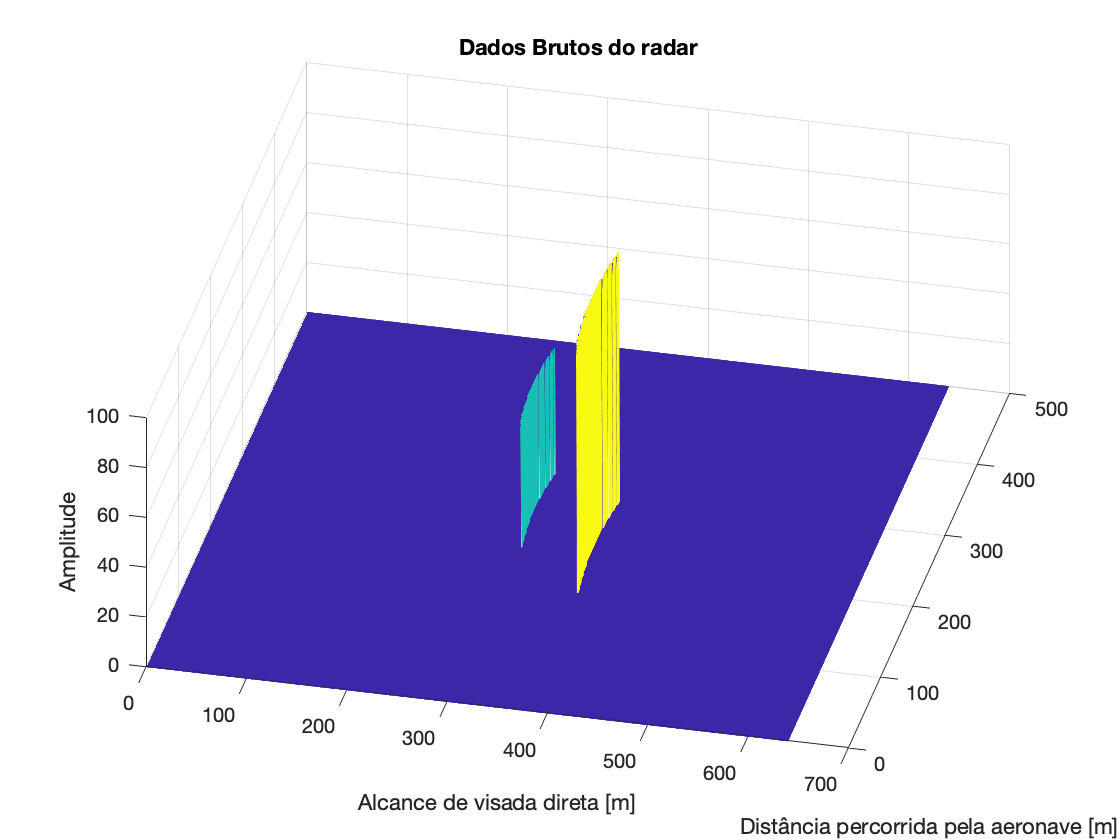

% Plot em perspectiva

mesh(rngIncrement*(1:512),x,matriz_signal)
view([12.9 55.6])
ylabel('Distância percorrida pela aeronave [m]')
xlabel('Alcance de visada direta [m]')
zlabel('Amplitude')
title('Dados Brutos do radar')